# Extract Coordinates from stl

This code is to transform stl into a mesh and list out all coordinates. The 'nodes' variable contains all coordinates that the part consists of in the STL file.

For github commits, refer to this: [https://www.mathworks.com/help/matlab/ref/matlab.git.gitrepository.commit.html](https://www.mathworks.com/help/matlab/ref/matlab.git.gitrepository.commit.html)


gm = fegeometry("simple_model.stl",AllowSelfIntersections=false)

gm =   fegeometry with properties:

       NumFaces: 8
       NumEdges: 14
    NumVertices: 10
       NumCells: 1
       Vertices: [10×3 double]
           Mesh: []




model = rotate(gm,90,[0 0 0], [1 0 0]); % Rotate 90 degrees about X to align height with Z-axis
new_gm = generateMesh(model);
nodes = new_gm.Mesh.Nodes           % every column is a point coordinate

nodes =     0.0056    0.0056   -0.0549   -0.0549   -0.0054   -0.0668   -0.0054   -0.0668   -0.0000   -0.0000    0.0733    0.0733    0.0576    0.0576   -0.0499   -0.0449   -0.0398   -0.0348   -0.0297   -0.0247   -0.0196   -0.0146   -0.0095   -0.0045    0.0006    0.0056    0.0056   -0.0549   -0.0549    0.0006   -0.0045   -0.0095   -0.0146   -0.0196   -0.0247   -0.0297   -0.0348   -0.0398   -0.0449   -0.0499   -0.0054   -0.0054   -0.0103   -0.0152   -0.0201   -0.0250   -0.0299   -0.0348   -0.0396   -0.0445
    0.0111   -0.0111    0.0111   -0.0111    0.0111    0.0111   -0.0111   -0.0111   -0.0483   -0.0483   -0.0000   -0.0000    0.0298    0.0298    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0037   -0.0037   -0.0037    0.0037   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0037    0.0037    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111 

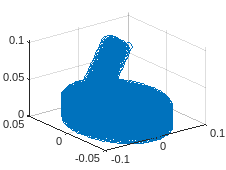

scatter3(nodes(1,:),nodes(2,:),nodes(3,:))

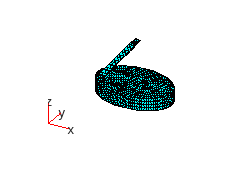



pdemesh(new_gm)